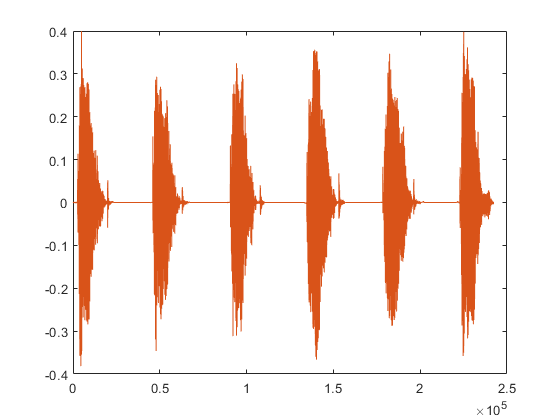

clf
fileName = 'Words\Dog.mp3';
[y, fs] = audioread(fileName);
duration = (length(y)-1)/fs;
plot(y)

sampleLength = fs;

[y1Combined] = preProcessor(fileName);
y1Len = length(y1Combined)

y1Len = 44100

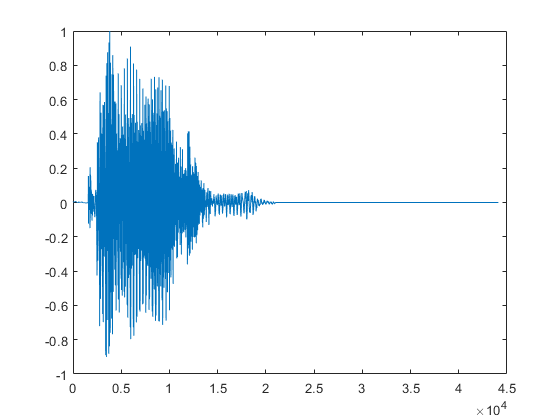


N = 2^12; %this is the N-parameter for the FFT. Out resolution, etc.
%============================
%    Sean:     We need a way to enfore a specific sample rate. Especially
%    since we resample. Not sure how we do that. Maybe since we know all
%    the samples come in with 44kHz, we can take a specific sample, because
%    a willy-nilly resample will change the meaning of the FFT indexes, so
%    for compatibility we need a standard.
%========

plot(y1Combined);

y1_resample = resample(y1Combined, N, y1Len);
y1RELen = length(y1_resample)

y1RELen = 4096

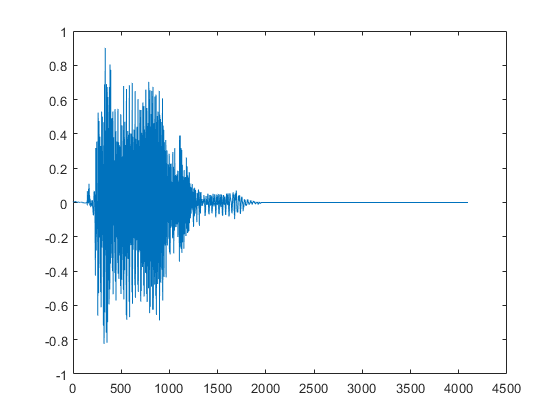

plot(y1_resample)

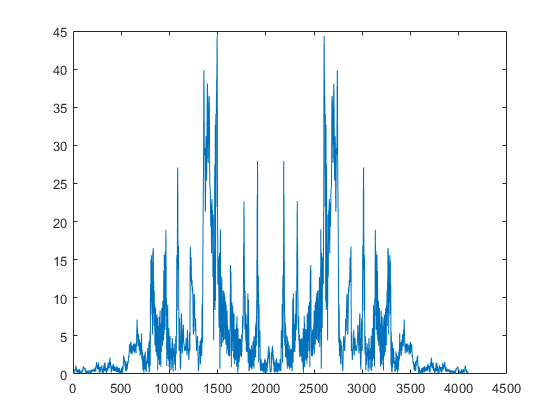

% sound(y1Norm,fs);
yFFT1 = abs(fftshift(fft(y1_resample)));
plot(yFFT1);

p2 = Phenome(2, yFFT1);

%{
sampleSpot =2.92;
round(sampleSpot*fs)
y2 = y(round(lowerBound*fs + sampleSpot):round(upperBound*fs + sampleSpot),1);
[y2Norm] = normalizeAudio(y2);
y2_resample = resample(y2Norm, N, y1Len);
% sound(y2Norm,fs)
plot(y2Norm)
plot(y2_resample)
yFFT2 = abs(fftshift(fft(y2_resample)));

plot(yFFT2);
p2_2 = Phenome(2, yFFT2);

err = p2.GetSquareError(p2_2);
%}